## 1 image

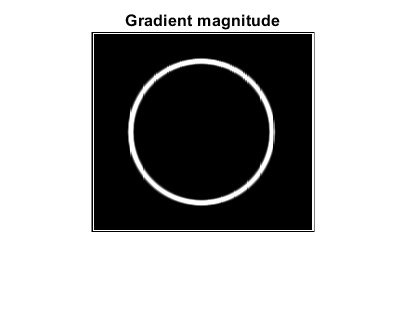

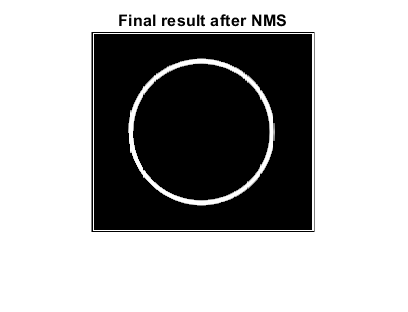

[IF1,IO1] = t1t("circlegrey.png");

## 2 image

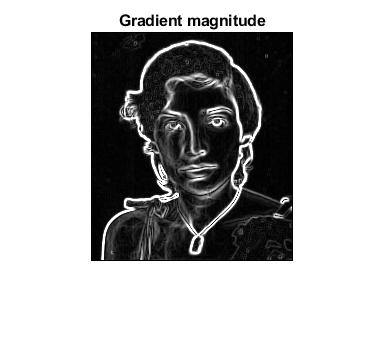

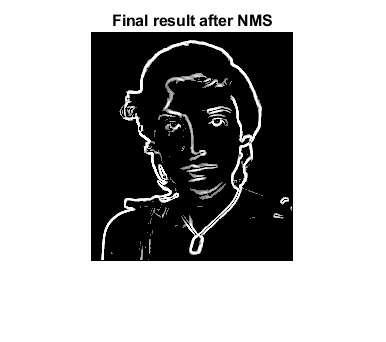

[IF2,IO2] = t1t("julia.png");

## 3 image

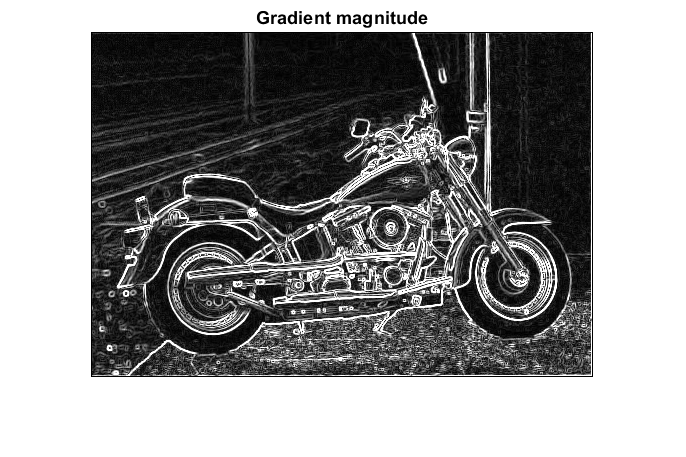

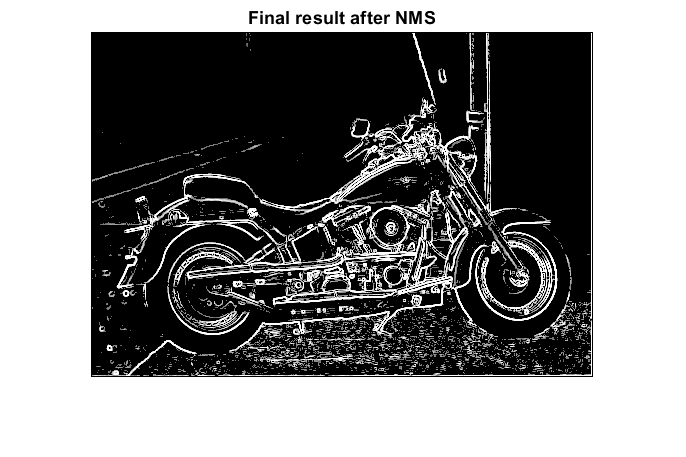

[IF3,IO3] = t1t("motor.png");

%montage({IF1,IF2,IF3},'Size',[1,3]);
%title("Gradient magnitute");
%montage({IO1,IO2,IO3},'Size',[1,3]);
%title("Final result after NMS");
export("t1.mlx");

## Main function

function [IF,IO] = t1t(imagename)
I = imread(imagename);

I = double(I);
IF = zeros(size(I));

Prewitt_Mx = [-1 0 1; -1 0 1; -1 0 1];
Prewitt_My = [-1 -1 -1; 0 0 0; 1 1 1];

Gx = zeros(size(I));
Gy = zeros(size(I));

for i = 1:size(I, 1) - 2
    for j = 1:size(I, 2) - 2
        x = sum(sum(Prewitt_Mx.*I(i:i+2, j:j+2)));
        y = sum(sum(Prewitt_My.*I(i:i+2, j:j+2)));
        
        Gx(i,j) = x;
        Gy(i,j) = y;
        IF(i+1, j+1) = sqrt(x.^2 + y.^2);         
    end
end

IF = uint8(IF);
figure, imshow(IF); title('Gradient magnitude');



X = size(IF, 1);
Y = size(IF, 2);
directions = zeros(X,Y);
for i = 1:X
    for j = 1:Y
        directions(i,j) = rad2deg(atan2(Gy(i,j), Gx(i,j)));
    end
end

result = zeros(X,Y);
for i = 2:X-1
    for j = 2:Y-1
        newD=0;
        if(directions(i,j) >= 0 && directions(i,j) < 22.5)
            newD = max(directions(i,j-1), directions(i,j+1));

        elseif(directions(i,j) >= 22.5 && directions(i,j) < 67.5)
            newD = max(directions(i-1,j-1), directions(i+1,j+1));

        elseif(directions(i,j) >= 67.5 && directions(i,j) < 112.5)
            newD = max(directions(i-1,j), directions(i+1,j));

        elseif(directions(i,j) >= 112.5 && directions(i,j) < 157.5)
            newD = max(directions(i-1,j+1), directions(i+1,j-1));

        else
            newD = max(directions(i,j-1),directions(i,j+1));
        end

        if(IF(i,j)<newD)
            result(i,j) = 0;
        else
            result(i,j) = IF(i,j);
        end
    end
end
IO = uint8(result);
for i = 1:size(IO, 1)
    for j = 1:size(IO, 2)
        if(IO(i,j) <= 100)
            IO(i,j) = 0;
        end
    end
end
figure, imshow(IO); title('Final result after NMS');
end